%% ============================
%  CONFIGURACIÓN
% =============================
Fs = 2000;                      % Frecuencia de muestreo
win_ms = 100;                  % Tamaño de ventana RMS (ms)
win = round(Fs * win_ms/1000); % Ventana en muestras

lowpass_fc = 5;                % Cutoff para el envelope
[b_env, a_env] = butter(4, lowpass_fc/(Fs/2), 'low');

%% ============================
% 1. CARGA DE DATOS
% =============================
emg = readtable('C:/Users/dante/OneDrive/Documentos/UDEM/PEF/PEF - IMT 2da prueba/PEF_IMT208.csv');


% Selección de canales (3:6 en tu archivo)
dataEMG = emg{8:end, 3:6};
validRows = all(isfinite(dataEMG), 2);
dataEMG = dataEMG(validRows, :);

N = size(dataEMG, 1);
t_emg = (0:N-1)' / Fs;

%% ============================
% 2. RECTIFICADO
% =============================
rectified = abs(dataEMG);

%% ============================
% 3. RMS MÓVIL
% =============================
RMS = zeros(size(rectified));

for ch = 1:size(rectified,2)
    RMS(:,ch) = sqrt(movmean(rectified(:,ch).^2, win));
end

%% ============================
% 4. FILTRADO PARA EMG ENVELOPE
% =============================
envelope = filtfilt(b_env, a_env, rectified);

%% ============================
% 5. iEMG (integral)
% =============================
iEMG = trapz(rectified) / Fs;

disp('iEMG por canal:');

iEMG por canal:


disp(iEMG);

    0.0011    0.0008    0.0004    0.0002



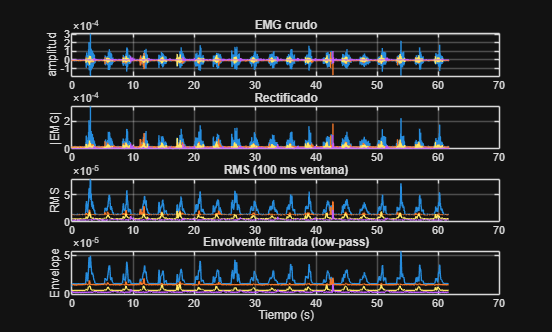


%% ============================
% 6. PLOTEO
% =============================
figure;

subplot(4,1,1);
plot(t_emg, dataEMG);
title('EMG crudo');
ylabel('amplitud');
grid on;

subplot(4,1,2);
plot(t_emg, rectified);
title('Rectificado');
ylabel('|EMG|');
grid on;

subplot(4,1,3);
plot(t_emg, RMS);
title(['RMS (' num2str(win_ms) ' ms ventana)']);
ylabel('RMS');
grid on;

subplot(4,1,4);
plot(t_emg, envelope);
title('Envolvente filtrada (low-pass)');
ylabel('Envelope');
xlabel('Tiempo (s)');
grid on;